# Basic image processing

Based on [this tutorial.](https://www.youtube.com/watch?v=nAVgUfk-ALE)

### Import and show an image in matlab

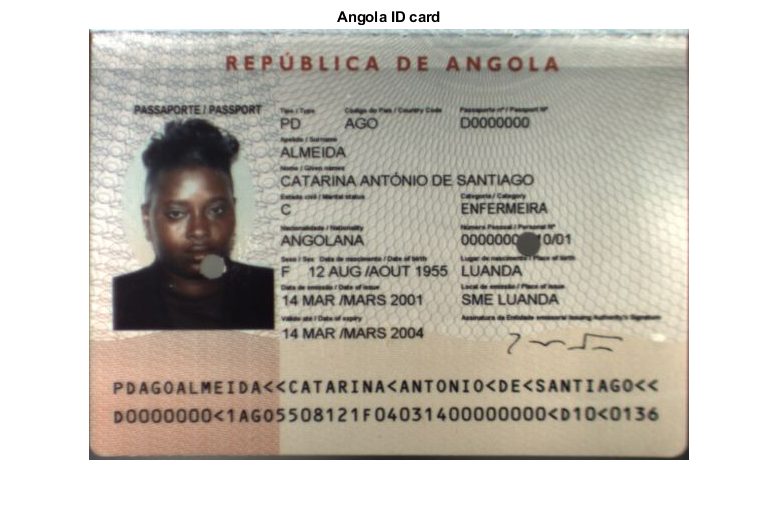

img1 = imread("images\AGO\AGO-AD-02001_D.jpg");
imshow(img1)
title("Angola ID card")

### Comparing two images

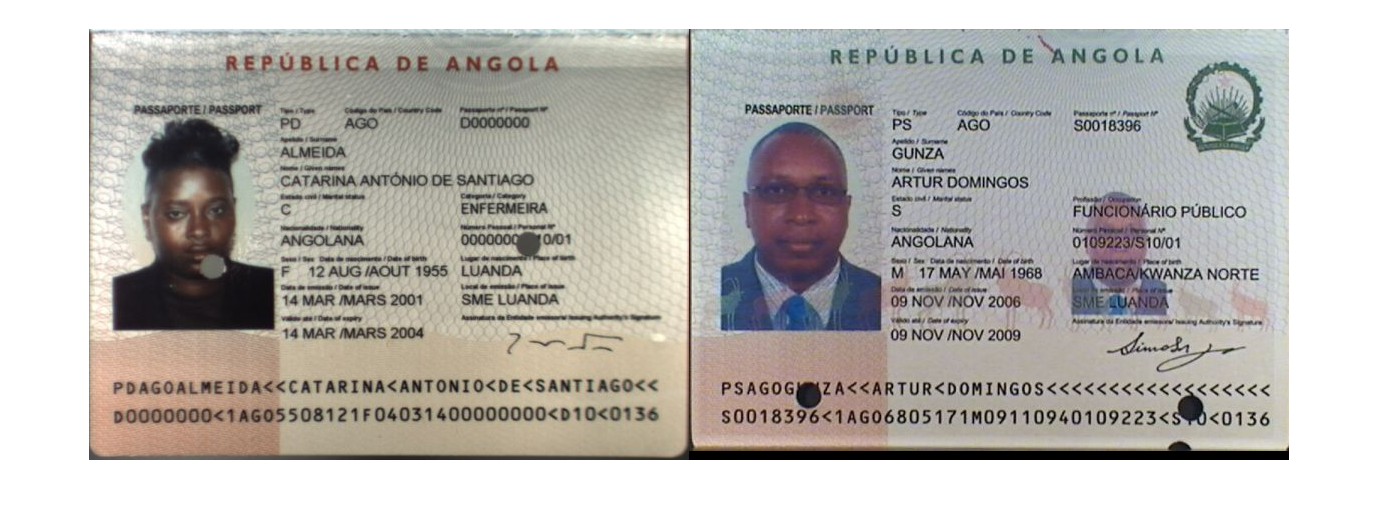

img2 = imread("images\AGO\AGO-AS-01001_S.jpg");
imshowpair(img1, img2, "montage")

### Convert to gray

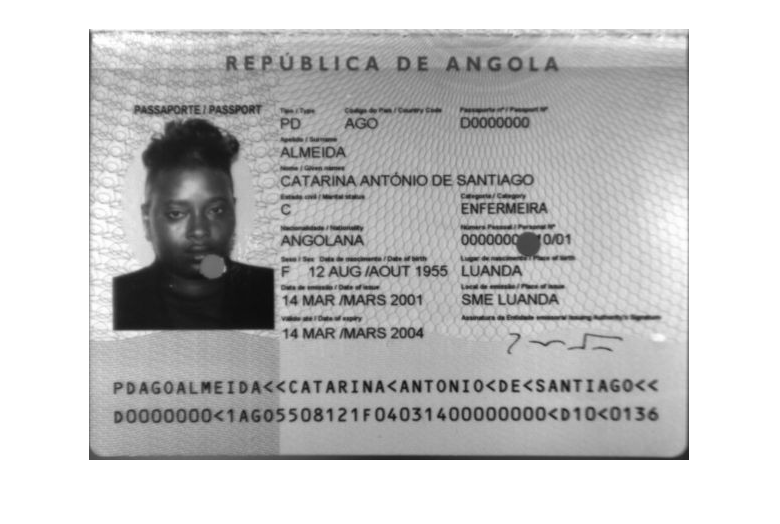

img = img1;
gray = im2gray(img);
imshow(gray)

### Create image histogram

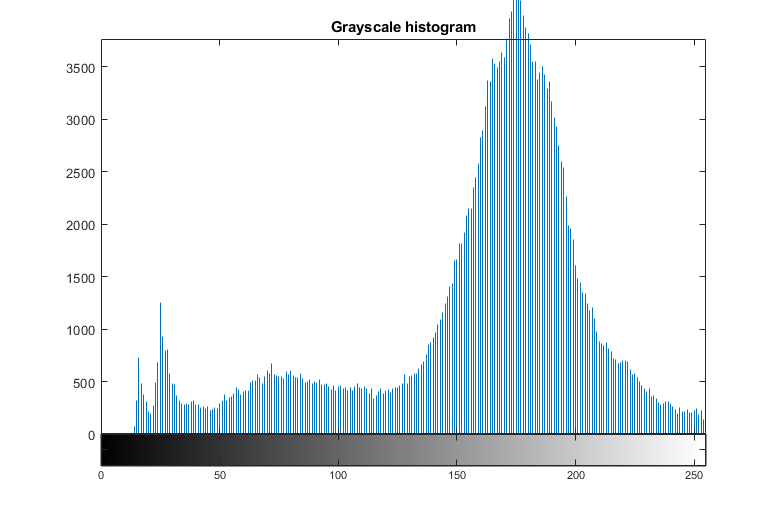

imhist(gray)
title("Grayscale histogram")

### Adjust contrast

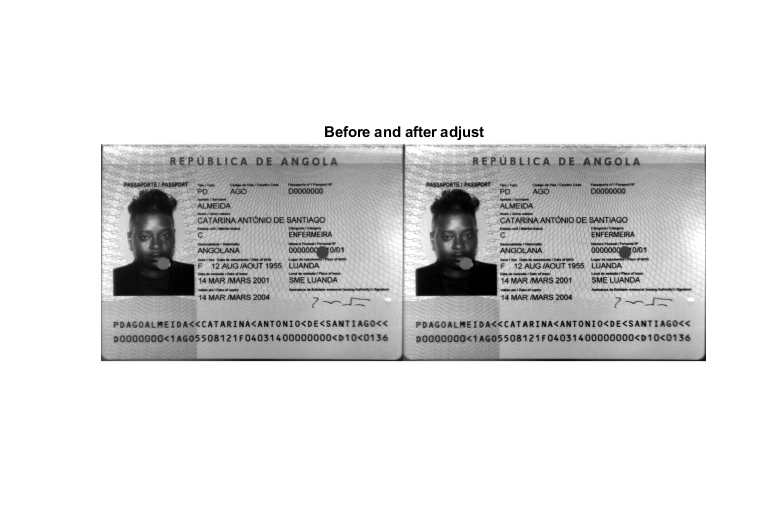

adj1 = imadjust(gray);
imshowpair(gray, adj1, "montage")
title("Before and after adjust")

### Create BW image using threshold

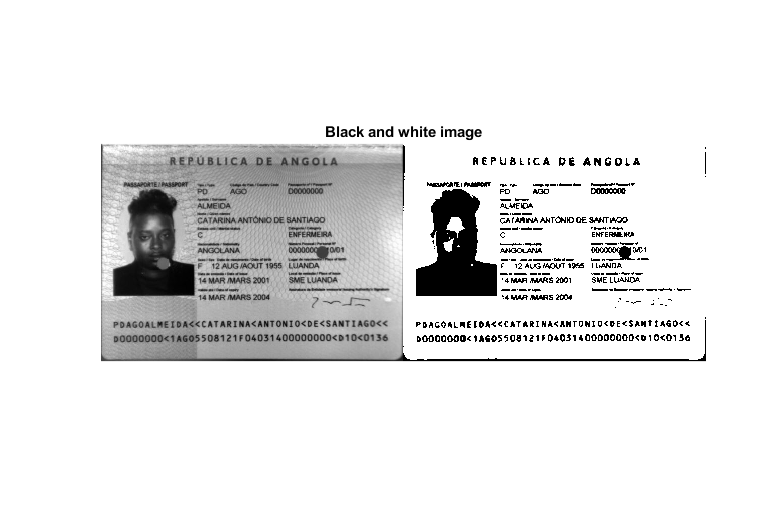

threshold = 0.45;
bw = im2bw(gray, threshold);
imshowpair(gray, bw, "montage")
title("Black and white image")

### Invert image

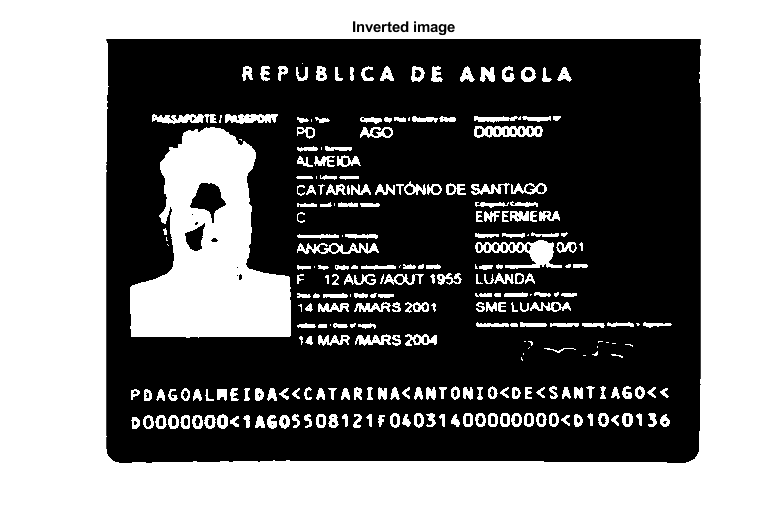

bw = ~bw;
imshow(bw)
title("Inverted image")

### Find a region of interest

Based on [this question](https://ch.mathworks.com/matlabcentral/answers/811295-how-to-detect-smarhtphone-s-screen-in-an-image).

First find the 3 largest boundary rectangles.

stats = regionprops(bw, 'BoundingBox','Area');
[v,i] = maxk([stats.Area], 3);

Display the bounging boxes.

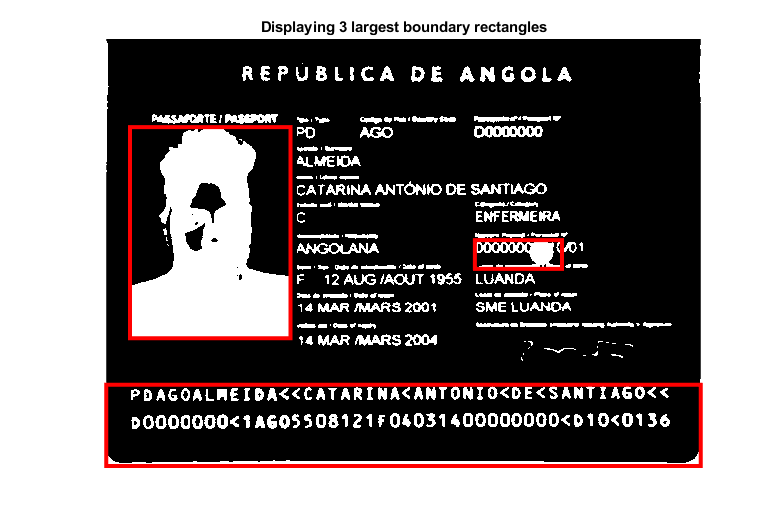

imshow(bw)
title("Displaying 3 largest boundary rectangles")
for index = 1 : length(i)
    rectangle('Position', stats(i(index)).BoundingBox,...
        'EdgeColor','r', 'LineWidth',3)
end

Crop part of the image

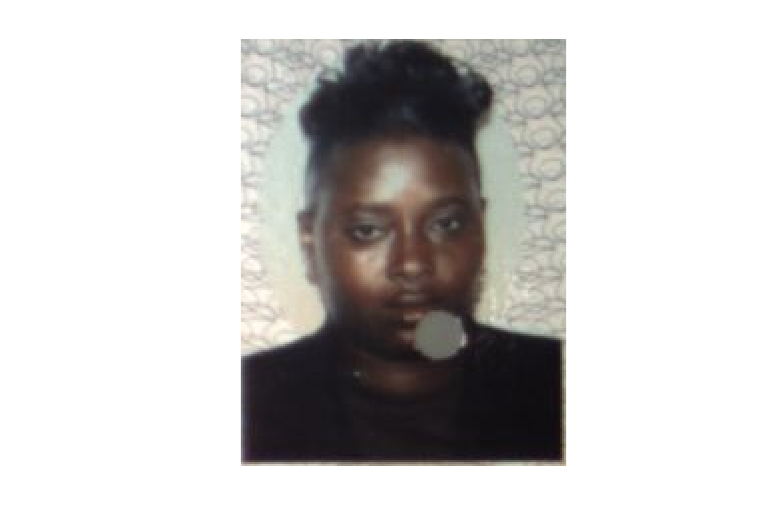

cropped = imcrop(img, stats(i(1)).BoundingBox);
imshow(cropped)